## 1. Calculate scaling factor

Frequency to filter.

clear all;
fSource                             =   3;

Lengths to show.

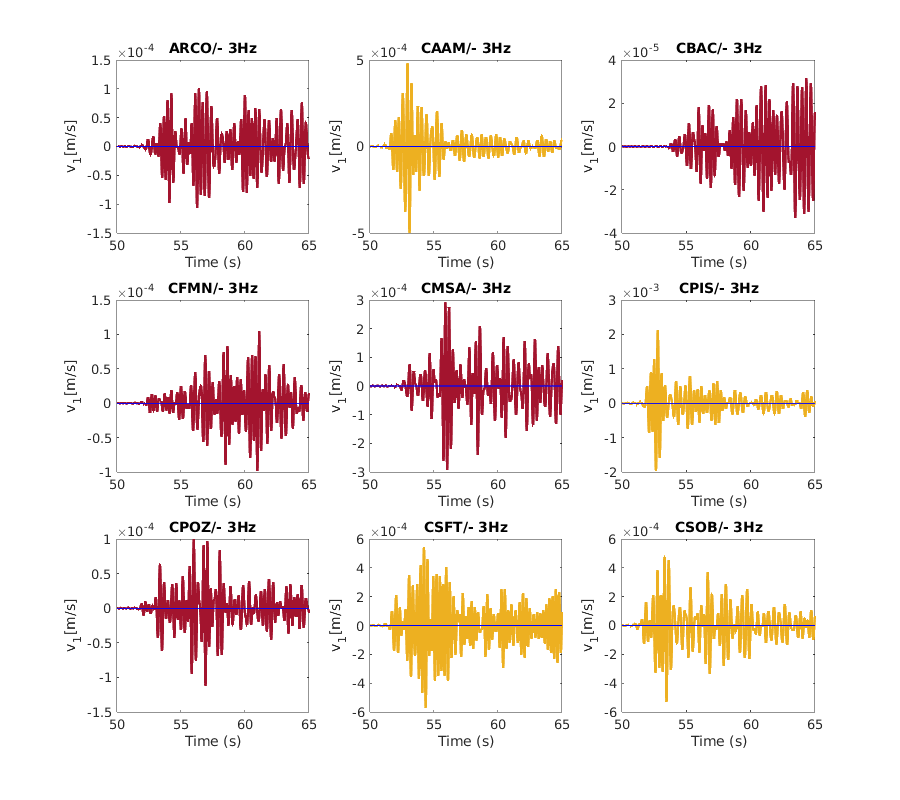

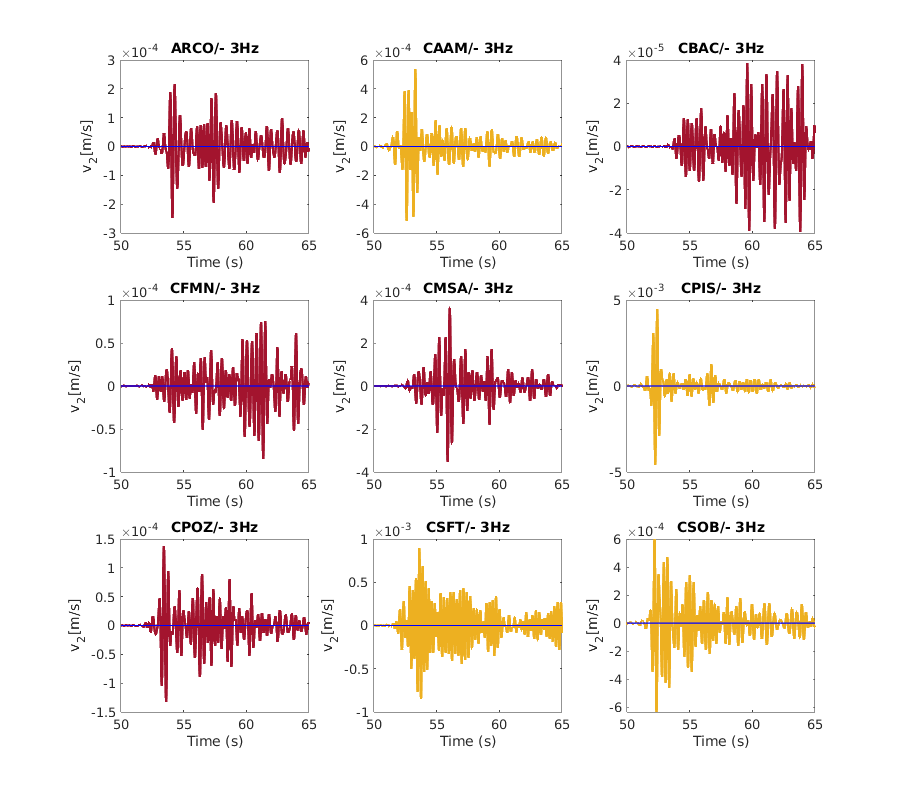

sca=zeros(9,3);
l11                                 =   50;
l22                                 =   65;
tt=load('rec_1.mat');
data=tt.data;
tt=load('rec_2.mat');
data2=tt.data;
tt=load('rec_3.mat');
data3=tt.data;
tt=load('rec_p.mat');
data4=tt.data;

dt=10^-3;
nt=2*10^4;
rec.time=zeros(3*size(data,2)+1,nt);
rec.time(1,:)=dt:dt:dt*nt;
rec.time(2:size(data,2)+1,:)=data';
rec.time(size(data,2)+2:size(data,2)*2+1,:)=data2';
rec.time(size(data,2)*2+2:size(data,2)*3+1,:)=data3';

for direc=1:3

Names of the files

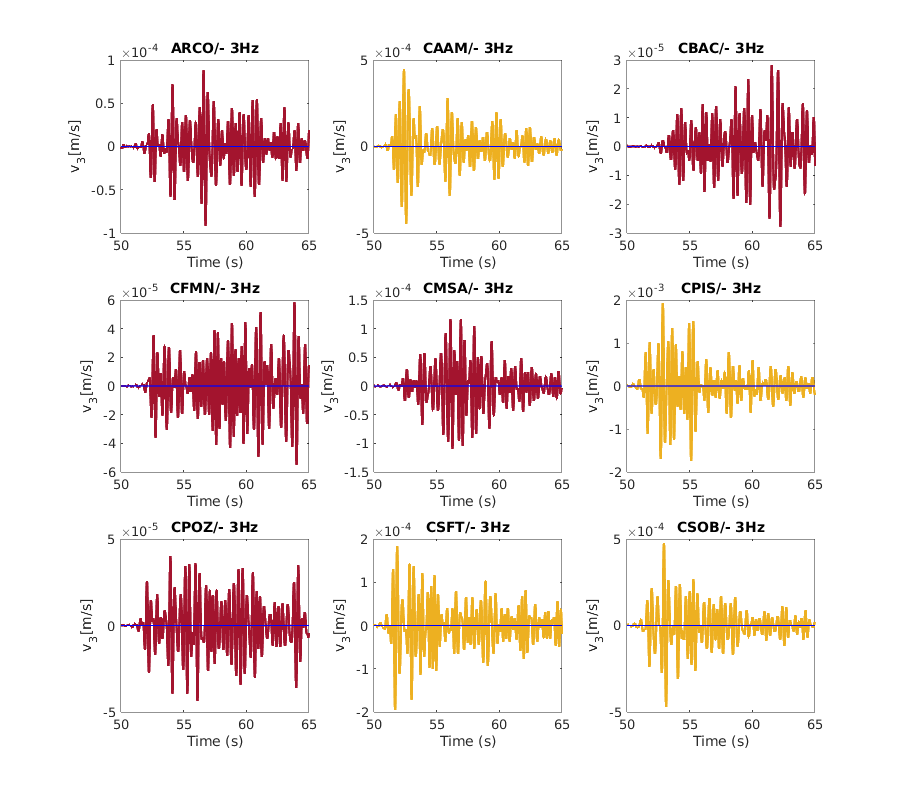

    if direc==1

        nmarker0                            =   './151007/*E.sac';
    end
    if direc==2
        nmarker0                            =   './151007/*N.sac';
    end
    if direc==3
        nmarker0                            =   './151007/*Z.sac';
    end
    list                                =   dir(nmarker0);
    filenames                           =   {list.name}';
    filedir                             =   {list.folder}';
    listasac                            =   strcat(filedir,'/',filenames);
    lls                                 =   length(listasac);
    [tempis,sismaew,SAChdr]             =   fget_sac(listasac{1});
    lsis                                =   length(sismaew);
    title1                              =   cell(lls,1);
    title2                              =   cell(lls,1);

Get coordinates of the stations

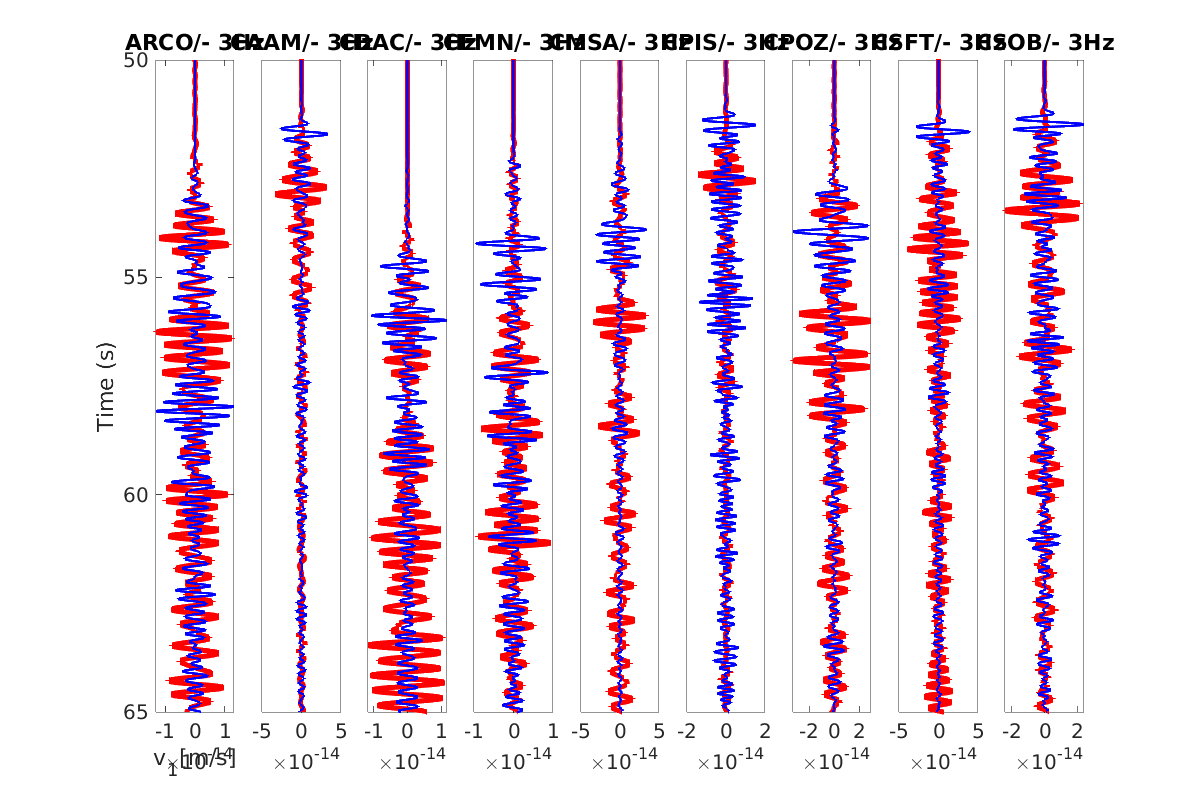

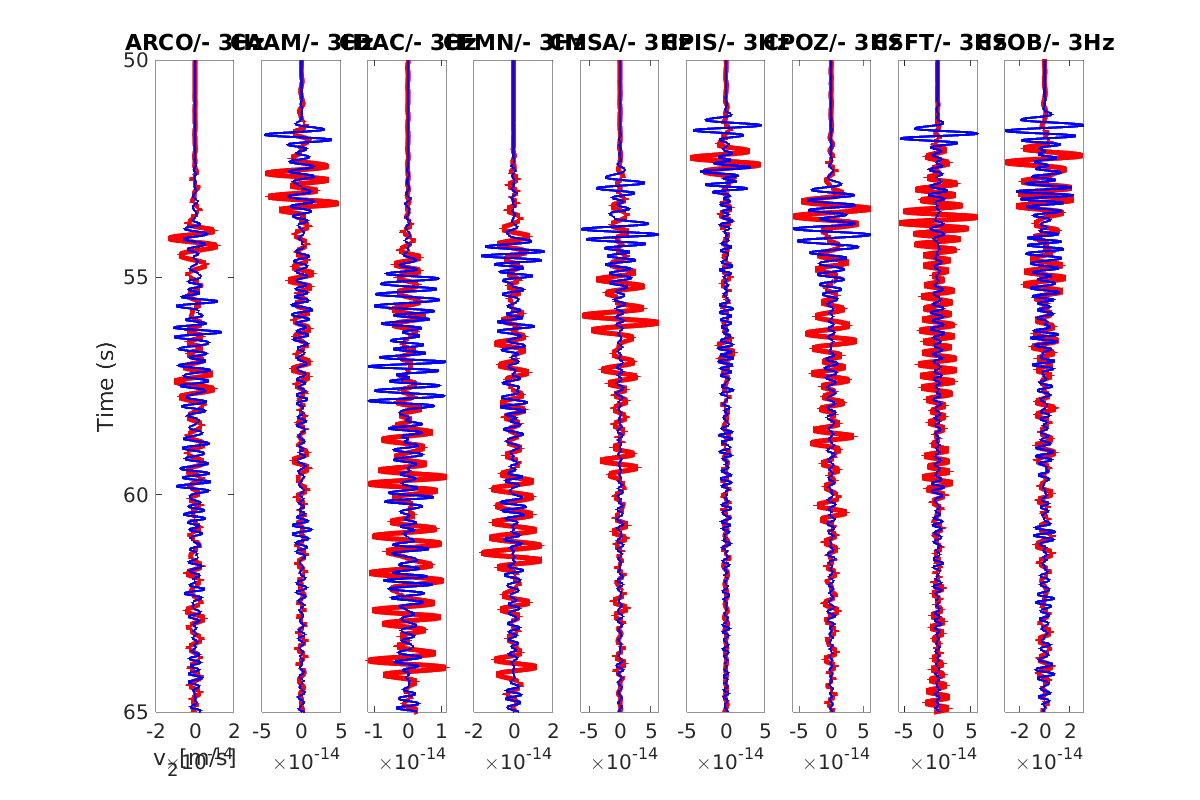

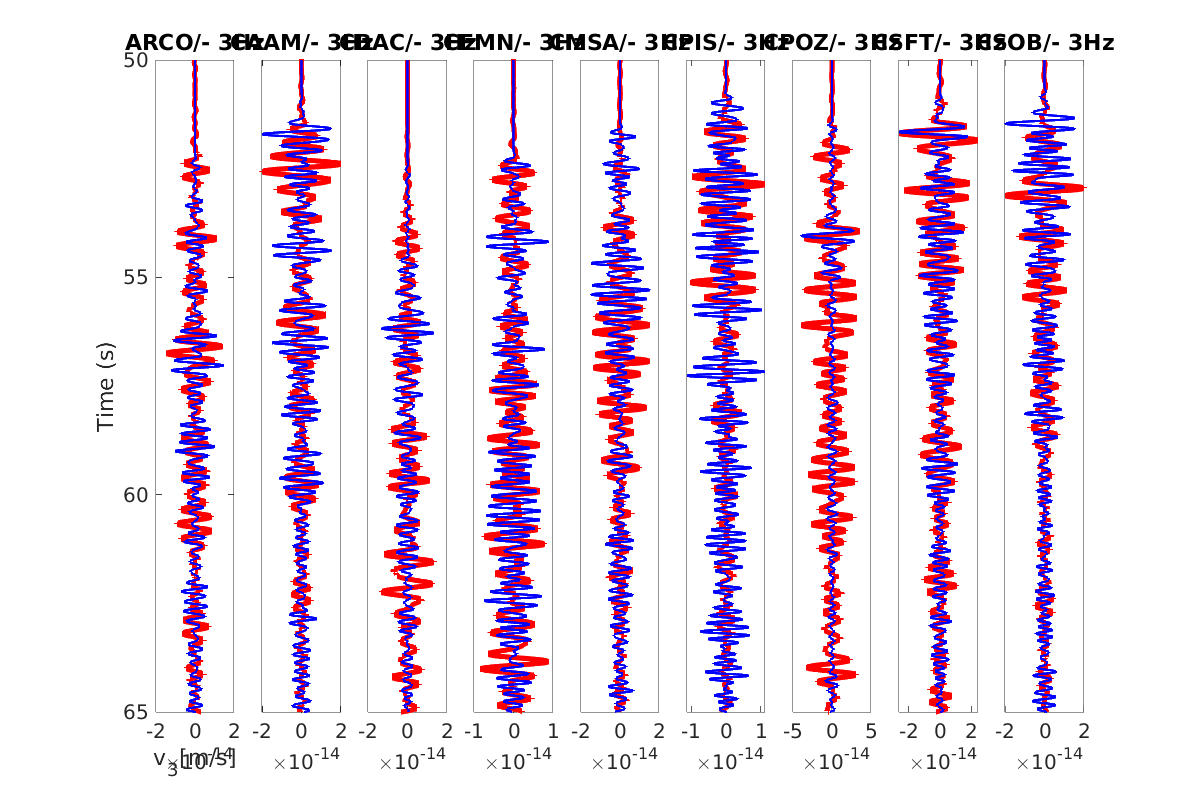

    filename = './Staz_even/stazioni_151007.txt';
    delimiterIn = ' ';
    headerlinesIn = 0;
    A = importdata(filename,delimiterIn,headerlinesIn);
    stazioni=A.data;
    namest=A.textdata;
    
    nmarker=nmarker0(9);
    tu                      =   tukeywin(lsis,0.05);%avoid windowing
    window=20;
    
    nmarker2=[nmarker0(9) '- ' num2str(fSource) 'Hz'];
    for i=1:lls
        title2(i)=strcat(namest(i), nmarker2);
    end
    
    hb=figure('Name','Filtered - 1 Hz',...
        'NumberTitle','off','Position',[1,200,900,800]);

Processing of the files and final figure.

    for i=1:lls

 Load data.

        [tempis,sisma1,SAChdr]=fget_sac(listasac{i});
        srate                       =   1/SAChdr.times.delta;

Creation of filter and application.

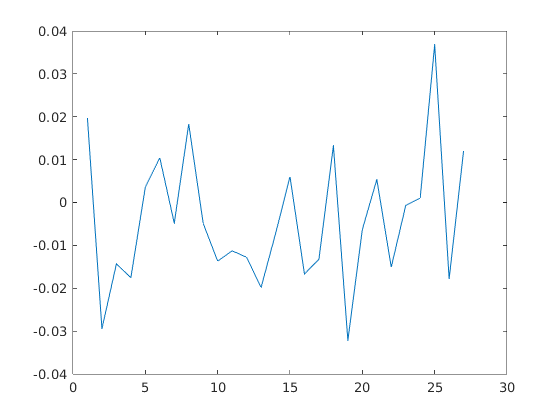

        Wn                      =   ([fSource-fSource/3 fSource+fSource/3]/srate*2);
        [z,p,k]                 =   butter(4,Wn,'bandpass');
        [sos,g]                 =   zp2sos(z,p,k);
        % sisma2  =   detrend(sisma1/SAChdr.data.scale,1);
        sisma2  =   detrend(sisma1/(A.data(i,7)*A.data(i,8)),1); %A.data(i,7)*A.data(i,8)
        sisma(i,:) = sisma2;

        tsisma         =   tu'.*sisma(i,:);
        fsisma         =   filtfilt(sos,g,tsisma);

Sub-panels for the figure.

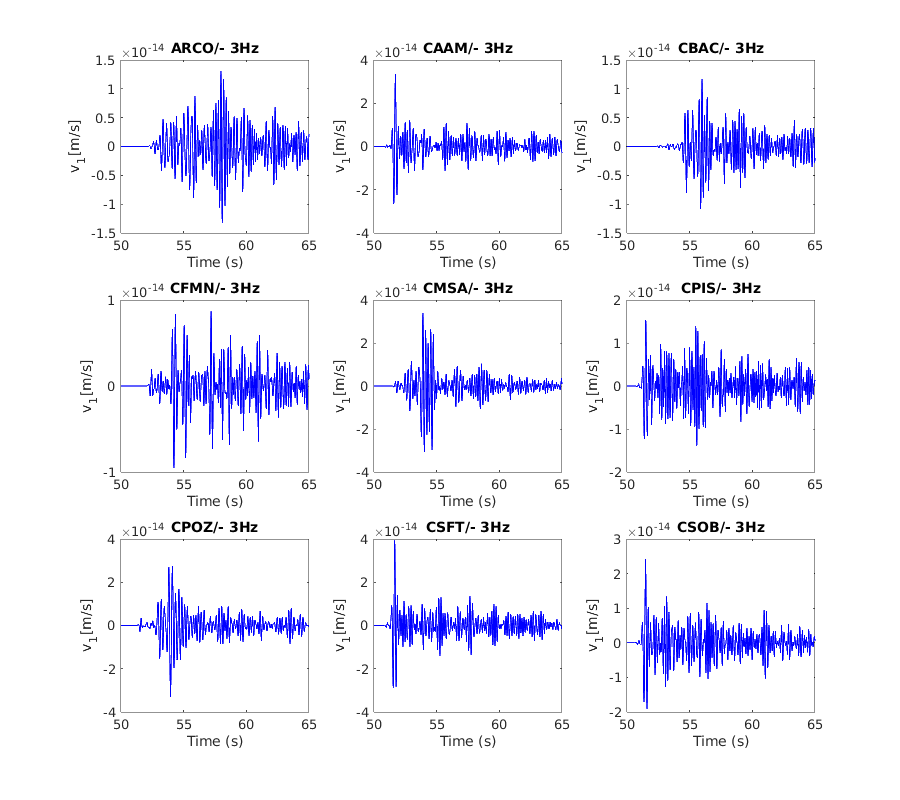

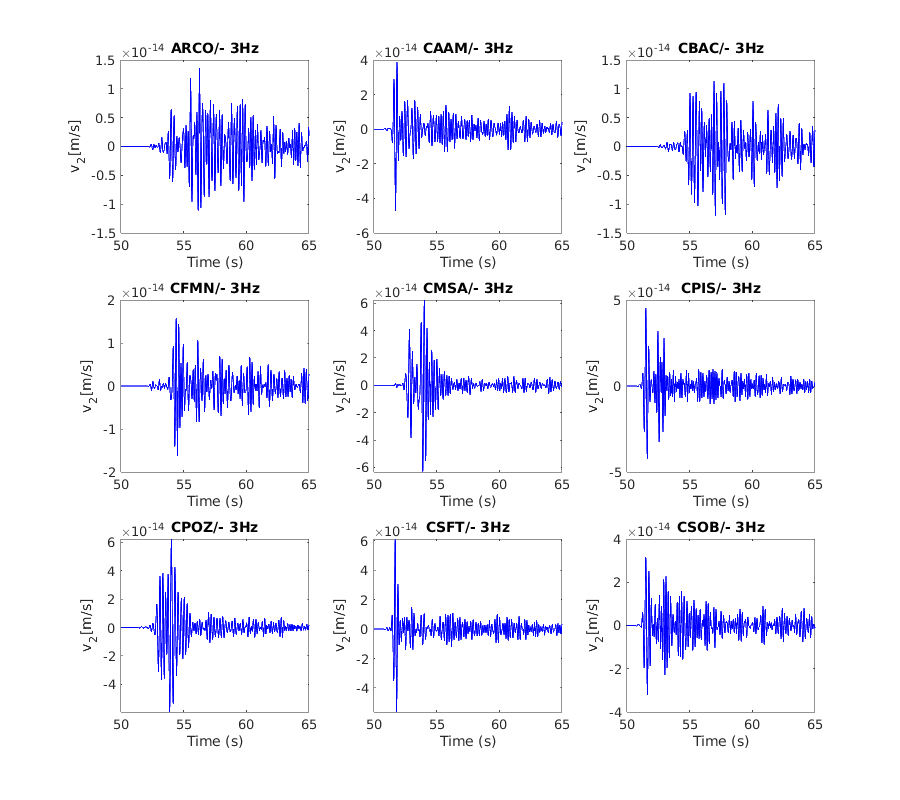

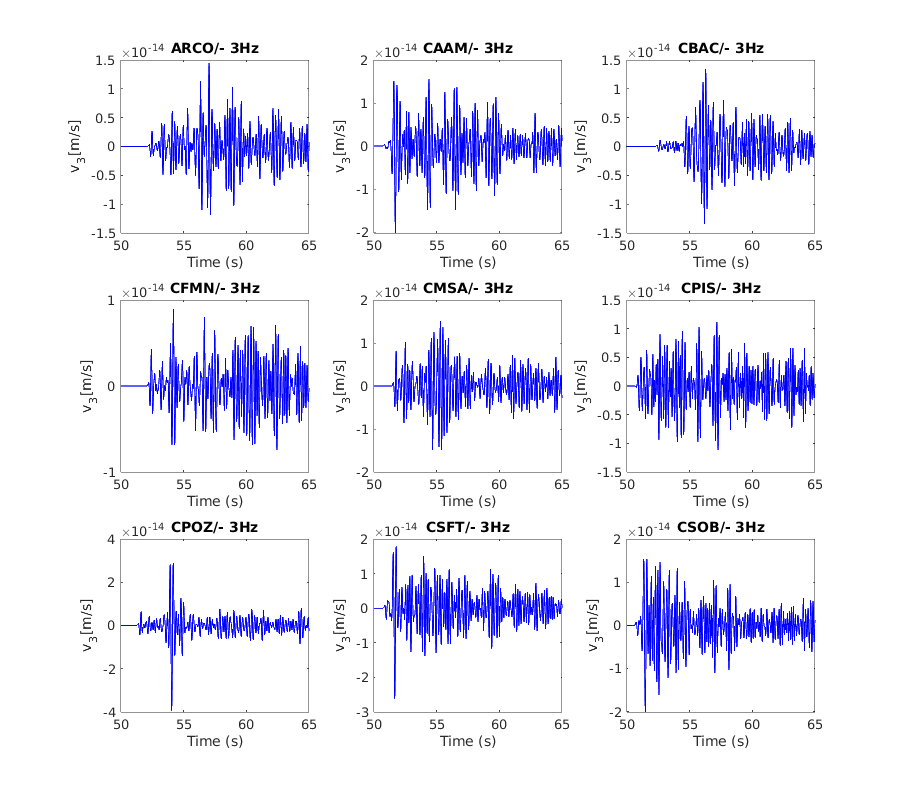

        tt=find(tempis<=l22 & tempis>=l11);
        sca(i,direc)=max(abs(fsisma(tt)))/max(abs(rec.time(1+i+9*(direc-1),:)));
        subplot(3,3,i)
        switch i
            case {1, 3, 4, 5, 7}
                plot(tempis,fsisma,'Color',[0.64,0.08,0.18],'LineWidth',2);
                hold on;
                plot(l11+(dt:dt:dt*nt),rec.time(1+i+9*(direc-1),:),'-','color','blue','LineWidth',1);
                hold on;
            case {2, 6, 8, 9}
                plot(tempis,fsisma,'Color',[0.93,0.69,0.13],'LineWidth',2);
                hold on;
                plot(l11+(dt:dt:dt*nt),rec.time(1+i+9*(direc-1),:),'-','color','blue','LineWidth',1);
                hold on;
        end
        title(title2{i})
        xlim([l11,l22]);
        xlabel('Time (s)'); ylabel(['v_' num2str(direc) '[m/s]']);
    end
    % print(gcf,['./P_rec_v' num2str(direc) '.png'],'-dpng','-r400');
end
hold off;

%{
figure;
for direc=1:3
    for i=1:6
        subplot(3,3,i)
        switch i
            case {1, 3, 4, 5, 7}
                plot(l11+(dt:dt:dt*nt),rec.time(1+i+9*(direc-1),:),'-','color','blue','LineWidth',1);
                hold on;
            case {2, 6, 8, 9}
                plot(l11+(dt:dt:dt*nt),rec.time(1+i+9*(direc-1),:),'-','color','blue','LineWidth',1);
                hold on;
        end
    end
    title(title2{i})
    xlim([l11,l22]);
    xlabel('Time (s)'); ylabel(['v_' num2str(direc) '[m/s]']);
end
hold off;
%}


## 2. Plot scaled recordings

Frequency to filter.

sca2=.2e11;
Rt=zeros(27,1500);

for direc=1:3

Names of the files

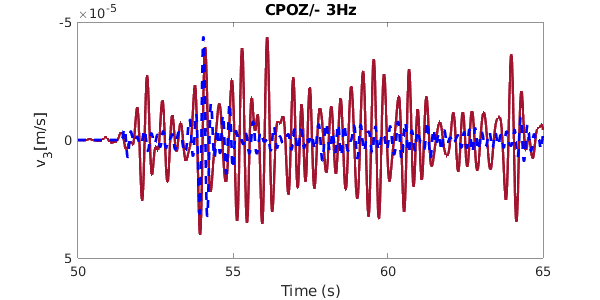

    if direc==1
        nmarker0                            =   './151007/*E.sac';
    end
    if direc==2
        nmarker0                            =   './151007/*N.sac';
    end
    if direc==3

        nmarker0                            =   './151007/*Z.sac';
    end
    list                                =   dir(nmarker0);
    filenames                           =   {list.name}';
    filedir                             =   {list.folder}';
    listasac                            =   strcat(filedir,'/',filenames);
    lls                                 =   length(listasac);
    [tempis,sismaew,SAChdr]             =   fget_sac(listasac{1});
    lsis                                =   length(sismaew);
    title1                              =   cell(lls,1);
    title2                              =   cell(lls,1);

Get coordinates of the stations

    filename = './Staz_even/stazioni_151007.txt';
    delimiterIn = ' ';
    headerlinesIn = 0;
    A = importdata(filename,delimiterIn,headerlinesIn);
    stazioni=A.data;
    namest=A.textdata;
    
    nmarker=nmarker0(9);
    tu                      =   tukeywin(lsis,0.05);%avoid windowing
    window=20;
    
    nmarker2=[nmarker0(9) '- ' num2str(fSource) 'Hz'];
    for i=1:lls
        title2(i)=strcat(namest(i), nmarker2);
    end
    
    hb=figure('Name','Filtered - 1 Hz',...
        'NumberTitle','off','Position',[1,200,1200,800]);

Processing of the files and final figure.

    for i=1:lls

 Load data.

        [tempis,sisma1,SAChdr]=fget_sac(listasac{i});
        srate                       =   1/SAChdr.times.delta;

Creation of filter and application.

        Wn                      =   ([fSource-fSource/3 fSource+fSource/3]/srate*2);
        [z,p,k]                 =   butter(4,Wn,'bandpass');
        [sos,g]                 =   zp2sos(z,p,k);
        % sisma2  =   detrend(sisma1/SAChdr.data.scale,1);
        sisma2  =   detrend(sisma1/(A.data(i,7)*A.data(i,8)),1);
        sisma(i,:) = sisma2;
        tsisma         =   tu'.*sisma(i,:);
        fsisma         =   filtfilt(sos,g,tsisma);

Sub-panels for the figure.

        
        subplot(1,9,i)
        plot(fsisma/sca(i,direc),tempis,'Color',[1,0,0],'LineWidth',4);
        hold on;
        plot(rec.time(1+i+9*(direc-1),:),l11+(dt:dt:dt*nt),'-','color','blue','LineWidth',2);
        set(gca,'Ydir','reverse');
       
        %set(gca,'Xtick',[round(min(rec.time(1+i+9*(direc-1),:)),4),round(max(rec.time(1+i+9*(direc-1),:)),4)]);
        %set(gca,'XtickLabel',1:8)
        title(title2{i})
        %xlim([min(rec.time(1+i+9*(direc-1),:)),max(rec.time(1+i+9*(direc-1),:))+10^-11]);
        ylim([l11,l22]);
        if i==1
            ylabel('Time (s)','fontsize',15);
            
            xlabel(['v_' num2str(direc) '[m/s]'],'fontsize',15);
        else
            set(gca,'ytick',[]);

        end
        set(gca,'fontsize', 15);
        Rt(i+(direc-1)*9,:)=fsisma(tt)*sca(i,direc);
        
    end
    print(gcf,['./rec_v' num2str(direc) '.png'],'-dpng','-r400');
end
Rt2=zeros(27,nt);
Rt2=imresize(Rt,[size(Rt,1),nt]);
xc_coefficient=zeros(27,1);
for i=1:size(Rt,1)
    xc=corrcoef(Rt2(i,:),rec.time(i+1,:));
    xc_coefficient(i)=xc(1,2);
end
figure;
plot(xc_coefficient)

## 3. Original simulated data

for direc=1:3

Names of the files

    if direc==1
        nmarker0                            =   './151007/*E.sac';
    end
    if direc==2
        nmarker0                            =   './151007/*N.sac';
    end
    if direc==3
        nmarker0                            =   './151007/*Z.sac';
    end
    list                                =   dir(nmarker0);
    filenames                           =   {list.name}';
    filedir                             =   {list.folder}';
    listasac                            =   strcat(filedir,'/',filenames);
    lls                                 =   length(listasac);
    [tempis,sismaew,SAChdr]             =   fget_sac(listasac{1});
    lsis                                =   length(sismaew);
    title1                              =   cell(lls,1);
    title2                              =   cell(lls,1);

Get coordinates of the stations

    filename = './Staz_even/stazioni_151007.txt';
    delimiterIn = ' ';
    headerlinesIn = 0;
    A = importdata(filename,delimiterIn,headerlinesIn);
    stazioni=A.data;
    namest=A.textdata;
    
    nmarker=nmarker0(9);
    tu                      =   tukeywin(lsis,0.05);%avoid windowing
    window=20;
    
    nmarker2=[nmarker0(9) '- ' num2str(fSource) 'Hz'];
    for i=1:lls
        title2(i)=strcat(namest(i), nmarker2);
    end
    
    hb=figure('Name','Filtered - 1 Hz',...
        'NumberTitle','off','Position',[1,200,900,800]);

Processing of the files and final figure.

    for i=1:lls

 Load data.

        [tempis,sisma1,SAChdr]=fget_sac(listasac{i});
        srate                       =   1/SAChdr.times.delta;

Creation of filter and application.

        Wn                      =   ([fSource-fSource/3 fSource+fSource/3]/srate*2);
        [z,p,k]                 =   butter(4,Wn,'bandpass');
        [sos,g]                 =   zp2sos(z,p,k);
        % sisma2  =   detrend(sisma1/SAChdr.data.scale,1);
        sisma2  =   detrend(sisma1/(A.data(i,7)*A.data(i,8)),1); %A.data(i,7)*A.data(i,8)
        sisma(i,:) = sisma2;
        tsisma         =   tu'.*sisma(i,:);
        fsisma         =   filtfilt(sos,g,tsisma);

Sub-panels for the figure.

        tt=find(tempis<=l22 & tempis>=l11);
        sca(i,direc)=max(abs(fsisma(tt)))/max(abs(rec.time(1+i+9*(direc-1),:)));
        subplot(3,3,i)
        switch i
            case {1, 3, 4, 5, 7}
                plot(l11+(dt:dt:dt*nt),rec.time(1+i+9*(direc-1),:),'-','color','blue','LineWidth',1);
                hold on;
            case {2, 6, 8, 9}
                plot(l11+(dt:dt:dt*nt),rec.time(1+i+9*(direc-1),:),'-','color','blue','LineWidth',1);
                hold on;
        end
        title(title2{i})
        xlim([l11,l22]);
        xlabel('Time (s)'); ylabel(['v_' num2str(direc) '[m/s]']);
    end
    % print(gcf,['./P_rec_v' num2str(direc) '.png'],'-dpng','-r400');
end

   for i=7

 Load data.

        [tempis,sisma1,SAChdr]=fget_sac(listasac{i});
        srate                       =   1/SAChdr.times.delta;

Creation of filter and application.

        Wn                      =   ([fSource-fSource/3 fSource+fSource/3]/srate*2);
        [z,p,k]                 =   butter(4,Wn,'bandpass');
        [sos,g]                 =   zp2sos(z,p,k);
        % sisma2  =   detrend(sisma1/SAChdr.data.scale,1);
        sisma2  =   detrend(sisma1/(A.data(i,7)*A.data(i,8)),1);
        sisma(i,:) = sisma2;
        tsisma         =   tu'.*sisma(i,:);
        fsisma         =   filtfilt(sos,g,tsisma);

Sub-panels for the figure.

        figure;
        set(gcf, 'Position',  [10, 10,600, 300])
        subplot(1,1,1)
        
                ax=plot(tempis,fsisma,'Color',[0.64,0.08,0.18],'LineWidth',2);
                hold on;
                ax2=plot(l11+(dt:dt:dt*nt),sca(i,direc)*rec.time(1+i+9*(direc-1),:),'--','color','blue','LineWidth',2);
                hold on;
    
                set(gca,'Ydir','reverse')
        title(title2{i})
        xlim([l11,l22]);
        xlabel('Time (s)');
        ylabel(['v_' num2str(direc) '[m/s]']);
        Rt(i+(direc-1)*9,:)=fsisma(tt)*sca2;
        %legend([ax,ax2],'data','no fluctuation','fluctuation','Location','southoutside','orientation','horizontal');
   end
